%% initialize environments
clc;
clear variables;

%% set AudioFileManipulator class parameters
input_file_path = "vaiueo2d.wav";

%% generate AudioFileManipulator instance and confirm properties
audio_file_manipulator = AudioFileManipulator(input_file_path);
audio_file_manipulator.load_properties();
audio_file_manipulator.display_properties();

--------------------------------------------
---------- Audio File Manipulator ----------
input_file_path : vaiueo2d.wav
output_file_path : default.wav
signal shape : (17500, 1)
sample_rate: 22050 [Hz]
             Filename: 'D:\名城大学\研究室\演習\MatlabPractice\SourceCode\Analysis\STRAIGHT\STRAIGHTV40_007b\vaiueo2d.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 22050
         TotalSamples: 17500
             Duration: 0.7937
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16

--------------------------------------------



%% set Cepstrum class parameters
start_point = 3748;  % あのスタート位置
continue_time = 32; % [ms]
continue_point = int32(continue_time * audio_file_manipulator.information.SampleRate / 1000);
window_mode = "hamming";
liftering_order_list = [0.24, 0.45, 0.9];  % [ms]

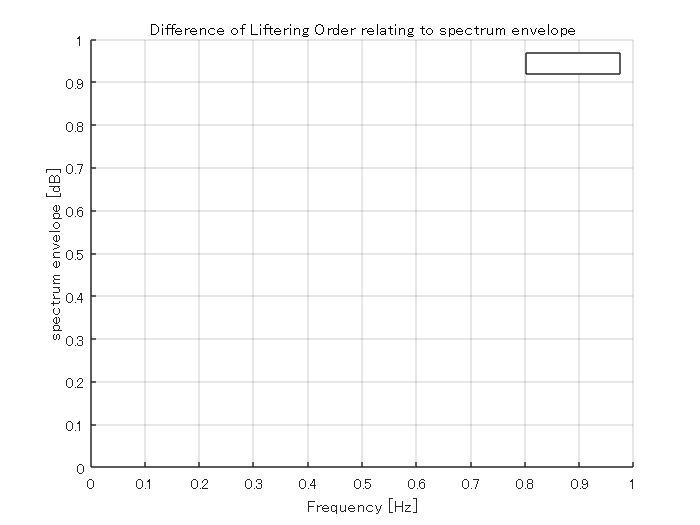

hold on;
grid on;
title("Difference of Liftering Order relating to spectrum envelope");
xlabel("Frequency [Hz]");
ylabel("spectrum envelope [dB]");
legend;

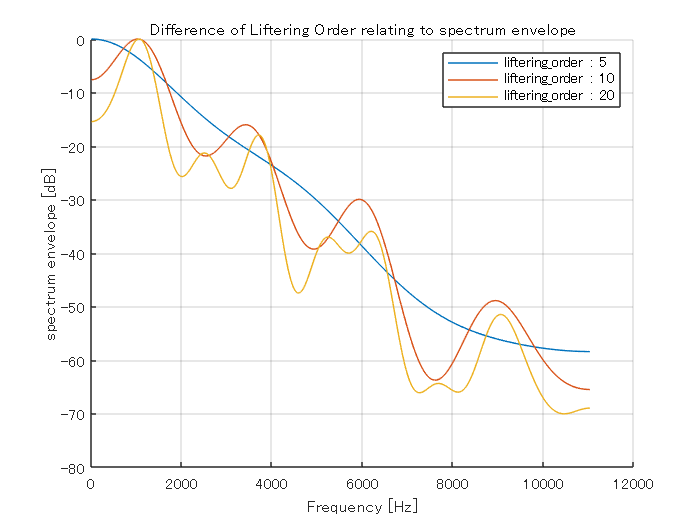

%% generate Cepstrum instance and confirm properties
for liftering_order_index = 1 : length(liftering_order_list)
    cepstrum = Cepstrum(audio_file_manipulator.signal(start_point : start_point + continue_point - 1), audio_file_manipulator.information.SampleRate, window_mode, liftering_order_list(liftering_order_index));
    plot((1 : length(cepstrum.get_amplitude_spectrum_envelope_dB())) / length(cepstrum.get_amplitude_spectrum_envelope_dB()) * floor(audio_file_manipulator.information.SampleRate / 2), cepstrum.get_amplitude_spectrum_envelope_dB(), "DisplayName", "liftering\_order : " + int2str(cepstrum.liftering_order));
end

%% save figure
saveas(gcf, "D:/名城大学/研究室/演習/data/Cepstrum/Difference_of_Liftering_Order_relating_to_spectrum_envelope.png");